# The impact of Cognitive Tasks on Network Properties after abrupt awakening (final)

### This analysis is almost complete!

but still need to make into markdown file

Note that this analysis basically fixes the issues i had in the previous analysis where i tried to replicate the figure 1 analysis where I plot the network properties of different bands but this time with different tasks. See the last set if figures in this file!!!

# Summary

Interestingly the network appears to change in opposite ways accross multiple dimensions

- the frequency band that changes - upper or lower

- the onset time of the change in the network - either network property is immediately effected or delayed

- the duration of change in the network- either for a single test bout, or extended

Notice that during the PV Task, the DELTA network is impacted immediately and temporaly after waking. Namely, clustering increases and path length decreases at time 1, but recovers quickly by time 2.

In contras during the Math Task, it is the BETA network that changes, and this change is not immediate and does not appear to recover. Namely, clustering increases and path length decreases during the seccond, third and fourth test bout.

## Get Data Set

clear;
DFM = dfmaster();  

##########
Getting GPSD during PVT Task. . . . . . . . . . . . 
	DONE

##########
Getting Network Props during PVT : . . . . . . . . . . . . 
	done
##########
Getting GPSD during KDT Task. . . . . . . . . . . 
	DONE

##########
Getting Network Props during KDT : . . . . . . . . . . . 
	done
##########
Getting GPSD during MATH Task. . . . . . . . . . . . 
	DONE

##########
Getting Network Props during MATH : . . . . . . . . . . . . 
	done
##########
Getting GPSD during GONOGO Task. . . . . . . . . . . . 
	DONE

##########
Getting Network Props during GONOGO : . . . . . . . . . . . . 
	done


clearvars -except DFM   
close all

## CLUSTERING and PATH LENGTH of LOW FREQUENCIES

### Low frequency components change only while engaging in PVT task. 

- Notice that during the PV Task, the DELTA network is impacted immediately and temporaly after waking. 

- Namely, clustering increases and path length decreases at time 1, but recovers quickly by time 2.

- further more, the DELTA network remains unnaffected while engagin in the math task

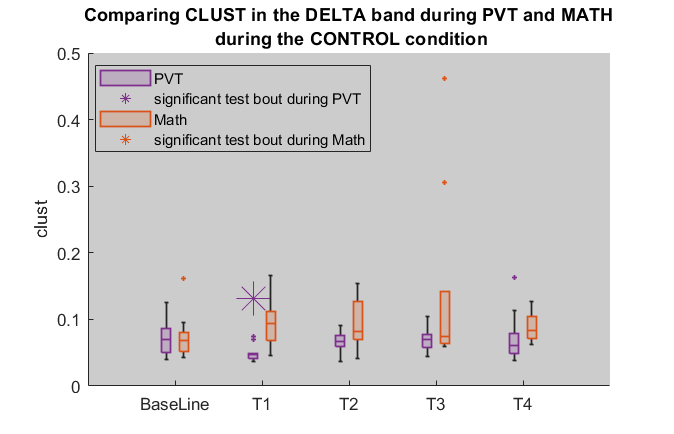

figanz_cogtestcmp(DFM, 'PVT', 'Math', 'clust', 'delta', 'control')
exportgraphics(gcf,'fig_clust_pvt_vs_math_beta_cntl.png','Resolution',100)

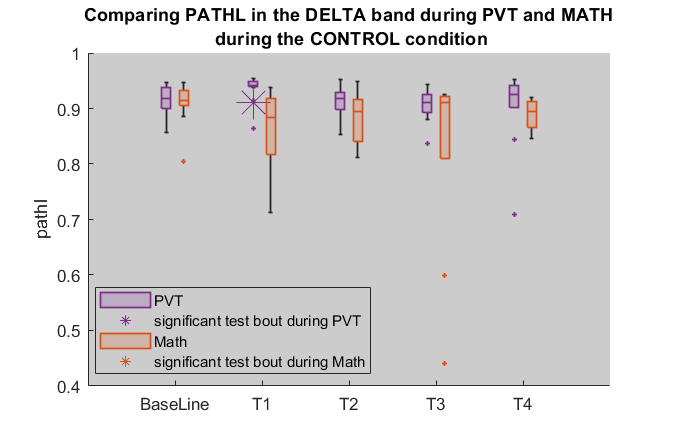

figanz_cogtestcmp(DFM, 'PVT', 'Math', 'pathl', 'delta', 'control')
exportgraphics(gcf,'fig_clust_pvt_vs_math_delta_cntl.png','Resolution',100)

## CLUSTERING and PATH LENGTH of HIGH FREQUENCIES

### High frequency networl components change only while engaging in Math task. 

- Notice that during the Math Task, it is the BETA network that changes

- Namely, clustering increases and path length decreases 

- Note that unlike the lower frequency, this change is not immediate nor does it recover by the fourth test bout. 

- Further more, these effects are only visible while engaging in the MATH task

#### Compare the Low and hight fequency componenets

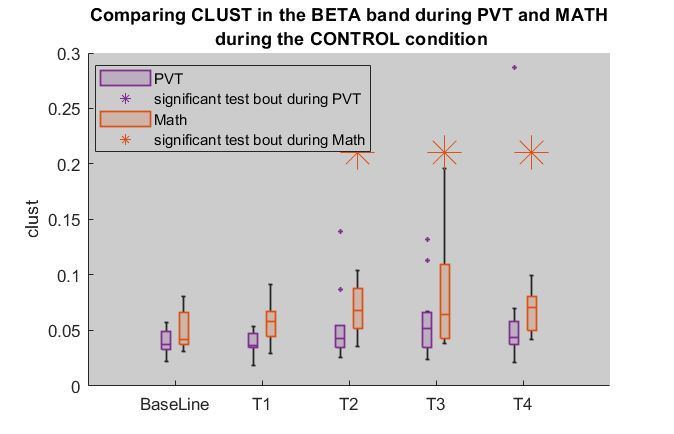

figanz_cogtestcmp(DFM, 'PVT', 'Math', 'clust', 'beta', 'control')
exportgraphics(gcf,'fig_pathl_pvt_vs_math_beta_cntl.png','Resolution',100)

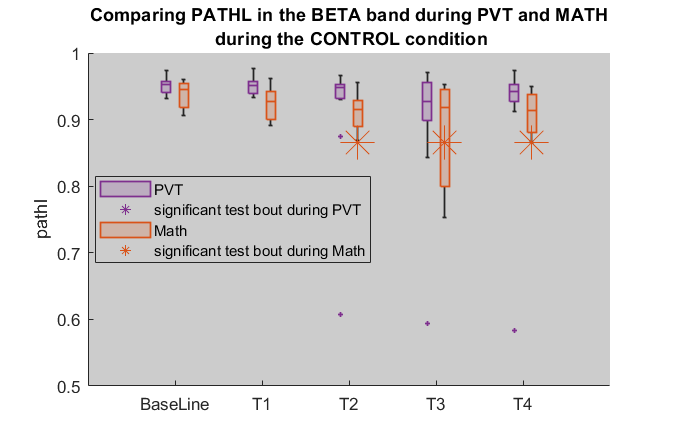


figanz_cogtestcmp(DFM, 'PVT', 'Math', 'pathl', 'beta', 'control')
exportgraphics(gcf,'fig_pathl_pvt_vs_math_beta_cntl.png','Resolution',100)

## Supplementary Figures: Original figure 1 analysis, but for all tasks. 

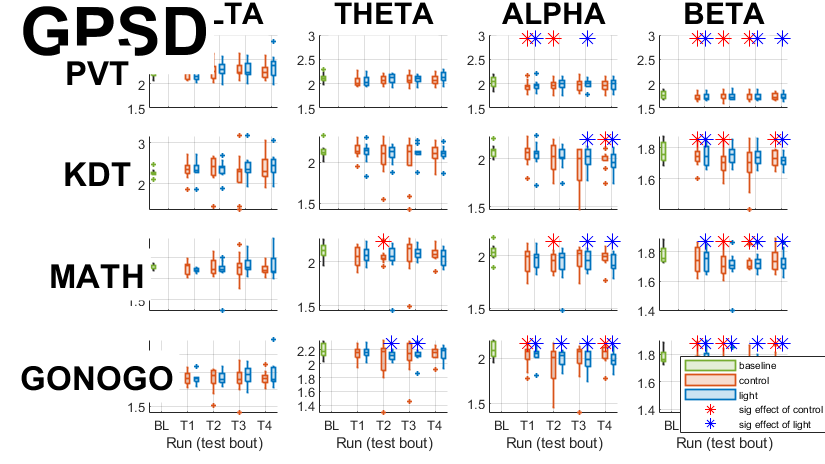

fig1anz(DFM, 'gpsd')
exportgraphics(gcf,'fig_fig1Original_gpsd.png','Resolution',100)

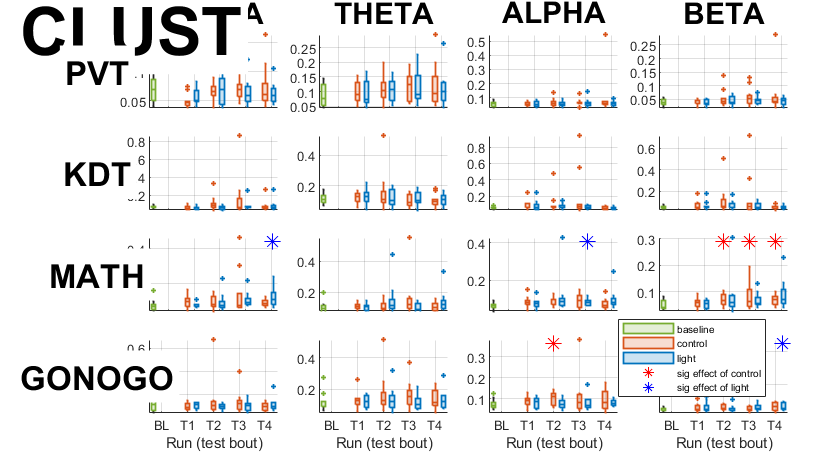


fig1anz(DFM, 'clust')
exportgraphics(gcf,'fig_fig1Original_clust.png','Resolution',100)

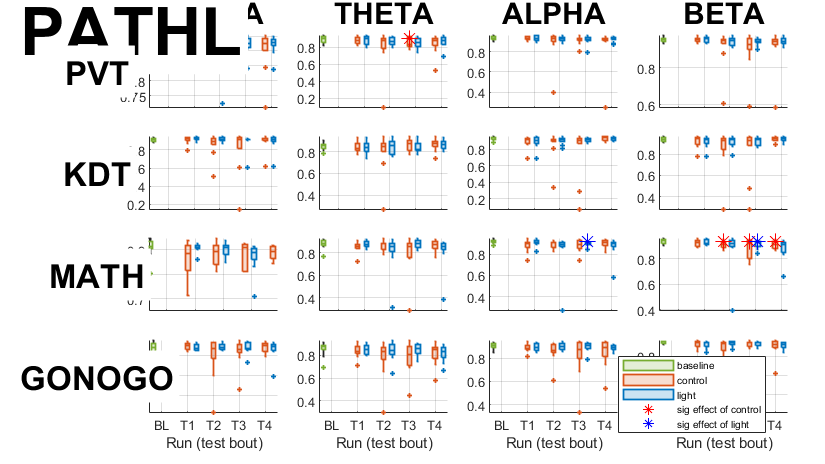


fig1anz(DFM, 'pathl')
exportgraphics(gcf,'fig_fig1Original_pathl.png','Resolution',100)

# Other Things To Do

subject assignment to conditions, need to know how to describe

order of tasks, random?

Make New plots of new claims in sfn abstact (if indeed are true

Use clustered regression techniques as discussed with jodi

- initial methods, for samples at 2 time points:

-  - Clustered robust standard error regression R package to use: huber white standard  regrsion package

- More complex method, for more that 2 time points:

- - longitudinal mixed models

- - New plots of new SFN claims

using wpli matrix, create a graph structure!!!! 

Assess visually using using matlabs graph structure and  wpli matrix\

recreate figure 2 with new data frame

recreate figure 3 with new data frame and topoplot functionality